close all

filename = 'C:\Users\pyeung\Downloads\HighwayLong3.csv_10.10.10.143_17038.csv';
T = readtable(filename, 'PreserveVariableNames', true);

x = T.("x (m)")

x =    22.0524
   23.4503
   24.6285
   27.7818
   33.4575
   34.4131
   42.9530
   39.6187
   19.2749
   18.6979


y = T.("y (m)")

y =    12.7474
   12.9428
   12.8393
   12.5772
   13.8869
   12.8659
   14.3358
   -2.4615
   -2.1979
   -3.1140


z = T.("z (m)")

z =     2.7009
    2.8733
    3.0191
    3.4082
    4.1057
    4.2240
    5.2731
    4.8646
    2.3667
    2.2959


intens = T.intensity

intens =         8737
        3656
        3897
        5903
        3562
        2823
        3088
        3378
       19899
        5551


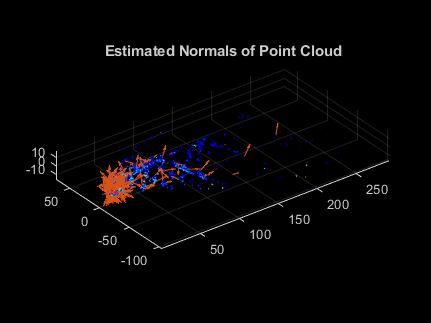

xyz = [x, y, z];

writematrix(xyz,'coordinates.csv')
pc = pointCloud(xyz, 'Intensity', intens);

lower = min([pc.XLimits pc.YLimits]);
upper = max([pc.XLimits pc.YLimits]);

xlimits = [lower upper];
ylimits = [lower upper];
zlimits = pc.ZLimits;

% player = pcplayer(xlimits,ylimits,zlimits);
%
% xlabel(player.Axes,'X (m)');
% ylabel(player.Axes,'Y (m)');
% zlabel(player.Axes,'Z (m)');
%
% for i = 1:360
%     view(player,pc);
% end
inc = 100;

normals = pcnormals(pc);
x1 = pc.Location(1:inc:end,1);
y1 = pc.Location(1:inc:end,2);
z1 = pc.Location(1:inc:end,3);
u = normals(1:inc:end,1);
v = normals(1:inc:end,2);
w = normals(1:inc:end,3);

writematrix(normals,'normals.csv');

figure
pcshow(pc)
title('Estimated Normals of Point Cloud')
hold on
quiver3(x1,y1,z1,u,v,w);
hold off

## Divide point cloud into cells

index = 1;
incx = 10;
incy = 10;
incz = 10;

r = zeros(size(x, 1),1);

for i = min(pc.XLimits)-1:incx:max(pc.XLimits)
    for j = min(pc.YLimits)-1:incy:max(pc.YLimits)
        for k = min(pc.ZLimits)-1:incz:max(pc.ZLimits)
            indices = x>i & x<=i+incx & y>j & y<=j+incy & z>k & z<=k+incz;
            %size(indices(indices==1))
            r(indices) = index;
            index = index + 1;
        end
    end
end

writematrix(r,'indices.csv');
cmap = jet(index);

## Create new point cloud with averaged normals

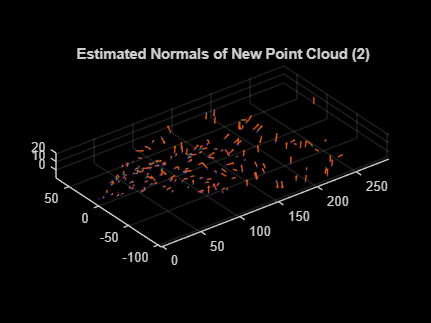

newNormals = zeros(index, 3);

for i = 1:index
    if size(x(r==i),1) > 0
        newNormals(i,1) = 100*mean(normals(r==i,1));
        newNormals(i,2) = 100*mean(normals(r==i,2));
        newNormals(i,3) = 100*mean(normals(r==i,3));
    end
end

x1 = newPc.Location(1:1:end,1);
y1 = newPc.Location(1:1:end,2);
z1 = newPc.Location(1:1:end,3);
u = newNormals(1:1:end,1);
v = newNormals(1:1:end,2);
w = newNormals(1:1:end,3);

writematrix(newNormals, 'newNormals.csv')

figure
pcshow(newPc)
title('Estimated Normals of New Point Cloud (2)')
hold on
quiver3(x1,y1,z1,u,v,w);
hold off


arr = [x1,y1,z1,u,v,w];

write(arr, 'newPc.csv')

Check for incorrect argument data type or missing argument in call to function 'write'.

## setup

%setup camera
points = [x,y,z,r];

cam = 200;
%setup image
imageSize = [1000,1000];
%create a tform matrix
angles = [5,-5,50]*pi/180;
position = [-25,-25,50];
tform = eye(4);
tform(1:3,1:3) = angle2dcm(angles(1),angles(2),angles(3));
tform(1:3,4) = position;
%project the points to create an image
[ image ] = points2Image(points, imageSize, cam, tform, 10,0.5, false)
%show the image
imshow(image);

function [ image ] = points2Image( points, imageSize, cam, tform, pointRadius, opacity, useMex )
%POINTS2IMAGE Uses a camera model to project 3D points onto a plane to
%generate an image
%
%   Required Inputs:
%   points- nxm set of 3d points, the 1st 3 columns are the point locations
%   (x,y,z) and the remaining coloumns the intensity values (i1,i2,etc), if
%   no intensity values are given, all points will have an intensity of 1
%   imageSize- 1x2 vector giving the height and width of the output image
%   [h,w]
%   cam- either a 3x4 camera projection matrix or a scalar focal length
%
%   Optional Inputs: (will give default values on empty array [])
%   tform- 4x4 transform to apply to points before projecting them (default
%   identity matrix)
%   pointRadius- radius of point in pixels (default 1)
%   opacity- scalar with range 0 to 1, specifies opacity of points (default
%   1)
%   useMex- use a mex file to speed up process (default true)
%
%   Outputs:
%   image- hxwx(m-3) output image of given size with (m-3) colour bands
%
%   References-
%   This code was used in generating the results for the journal paper
%   Multi-modal sensor calibration using a gradient orientation measure
%   http://www.zjtaylor.com/welcome/download_pdf?pdf=JFR2013.pdf as well
%   as several of my other publications
%
%   This code was written by Zachary Taylor
%   zacharyjeremytaylor@gmail.com
%   http://www.zjtaylor.com

## check inputs

validateattributes(points, {'numeric'},{'2d'});
if(size(points,2) < 3)
    error('points must have atleast 3 columns, currently has %i',size(points,2));
end
validateattributes(imageSize, {'numeric'},{'size',[1,2],'positive','integer'});
validateattributes(cam, {'numeric'},{});
if(length(cam) == 1)
    cam = [cam,0,imageSize(2)/2,0;0,cam,imageSize(1)/2,0;0,0,1,0];
end
validateattributes(cam, {'numeric'},{'size',[3,4]});
if(nargin < 4)
    tform = [];
end
if(isempty(tform))
    tform = eye(4);
else
    validateattributes(tform, {'numeric'},{'size',[4,4]});
end
if(nargin < 5)
    pointRadius = [];
end
if(isempty(pointRadius))
    pointRadius = 1;
else
    validateattributes(pointRadius, {'numeric'},{'scalar','positive','integer'});
end
if(nargin < 6)
    opacity = [];
end
if(isempty(opacity))
    opacity = 1;
else
    validateattributes(opacity, {'numeric'},{'scalar','positive'});
    if((opacity > 1) || (opacity < 0))
        error('Opacity must be in range 0 to 1');
    end
end
if(nargin < 7)
    useMex = [];
end
if(isempty(useMex))
    useMex = true;
else
    validateattributes(useMex, {'logical'},{'scalar'});
end
%convert elements which require precision to doubles
points = double(points);
tform = double(tform);
cam = double(cam);

## run image generation

%create filter
disk = fspecial('disk',pointRadius);
disk = opacity.*disk./max(disk(:));
%split points into locations and colour
locs = [points(:,1:3), ones(size(points,1),1)];
if(size(points,2) > 3)
    colours = points(:,4:end);
else
    colours = ones(size(points,1),1);
end
%move camera position
locs = (tform*locs')';
%sort points by distance from camera
dist = sum(locs(:,1:3).^2,2);
[~,idx] = sort(dist,'descend');
locs = locs(idx,:);
colours = colours(idx,:);
%project points into 2D
locs = (cam*locs')';
keep = locs(:,3) > 0;
locs = locs(keep,:);
colours = colours(keep,:);
locs = locs(:,1:2)./repmat(locs(:,3),1,2);
locs = round(locs);
%remove unseen points
keep = (locs(:,1) >= -size(disk,1)) & ...
    (locs(:,1) < (imageSize(2) + size(disk,1))) & ...
    (locs(:,2) >= -size(disk,2)) & ...
    (locs(:,2) < (imageSize(1) + size(disk,2)));
locs = locs(keep,:);
colours = colours(keep,:);
%form image
if(useMex)
    %compile if required
    if(exist('colourImage') ~= 3)
        mex colourImage.cpp;
    end
    image = colourImage(locs, colours, disk, uint32(imageSize));
else
    %run slow non-mex version of code
    image = zeros([imageSize,size(colours,2)]);
    for i = 1:size(locs,1)
        for iy = -pointRadius:pointRadius
            for ix = -pointRadius:pointRadius
                valid = (locs(i,1)+ix >= 0) & ...
                    (locs(i,1)+ix < imageSize(2)) & ...
                    (locs(i,2)+iy >= 0) & ...
                    (locs(i,2)+iy < imageSize(1));
                if(valid)
                    opac = disk(iy+pointRadius+1,ix+pointRadius+1);
                    col = (1-opac)*image(locs(i,2)+iy+1, locs(i,1)+ix+1,:);
                    image(locs(i,2)+iy+1, locs(i,1)+ix+1,:) = col(:)' + opac*colours(i,:);
                end
            end
        end
    end
end
end